clear all
close all

load catchingData

addpath('graphics')
addpath('subfunctions')

Remember to check your coordinates systems!

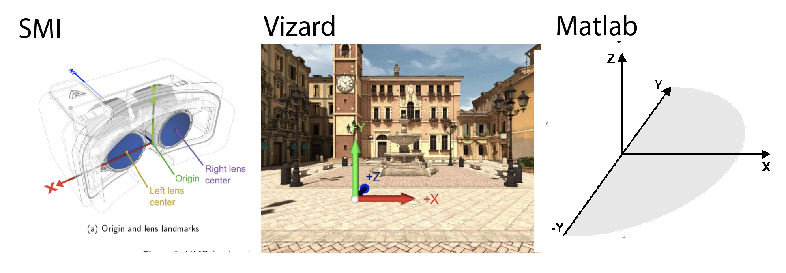

% Convert SMI data into Vizard coordinates
etData.cycEyeInHead_fr_XYZ(:,1) = -etData.cycEyeInHead_fr_XYZ(:,1);

Now, lets just go ahead and calculate the GIW angle for each frame.


for fr = 1:length(etData.viewMat_fr_4x4)
    
    gazePointInWorld_fr_xyzw(fr,:) = etData.viewMat_fr_4x4{fr} * [etData.cycEyeInHead_fr_XYZ(fr,:)  1]';
    
end

Here's the thing: that little bit of code just took a unit vector and moved it to a location 1 m away from the head in the world frame. Although the point lies along the gaze-in-world vector, it is no longer a normalized vector. 

To convert it into a normalized vector, we can just subtract the view position.

for fr = 1:length(etData.viewMat_fr_4x4)
    
    giwDir_xyz = gazePointInWorld_fr_xyzw(fr,1:3) - etData.viewPos_fr_XYZ(fr,:);
    
    % For good measure, normalize.
    giwDir_fr_xyz(fr,:) = giwDir_xyz  / norm(giwDir_xyz );
end

Lets also calculate the direction from the eye to the ball

for fr = 1:length(etData.viewMat_fr_4x4)
    
    eyeToBallDir_xyz = etData.ballPos_fr_XYZ(fr,:) - etData.viewPos_fr_XYZ(fr,:);
    
    % For good measure, normalize.
    eyeToBallDir_fr_xyz(fr,:) =  eyeToBallDir_xyz   / norm(eyeToBallDir_xyz);
end


Lets add these to our structure

etData.giwDir_fr_xyz = giwDir_fr_xyz;
etData.eyeToBallDir_fr_xyz = eyeToBallDir_fr_xyz;

The result is a direction that accounts for the rotation of the subject's eyes-in-the-head, as well as the head-in-the-world.

ballRenderOn_tr = find(strcmp(etData.eventFlag_fr,'ballRenderOn'));
fr = ballRenderOn_tr(1);

close all
figure(2)
cla
hold on
axis equal
%campos([2,2,2])
grid on 
xlabel 'x'
ylabel 'y'
zlabel 'z'
xlim([-2,2])
ylim([-2 2])
zlim([0 3])

origin = etData.viewMat_fr_4x4{fr}(1:3,4);
%campos([origin' + [-1,1,1]])%
%camtarget(origin)

%% Draw the EIH signal
viewMat_4x4 = etData.viewMat_fr_4x4{fr}

viewMat_4x4 =     0.9924    0.1142   -0.0450   -0.9728
   -0.0908    0.9296    0.3573    1.7297
    0.0827   -0.3505    0.9329   -0.0523
         0         0         0    1.0000


viewMat_4x4(:,4) = [0,0,0,1];
headAxH = gdDrawAxisAtOrigin(viewMat_4x4,.2,.02);

gaze_xyzw_pt = [giwDir_fr_xyz(fr,:); [0,0,0]]';
gL = plot3(gaze_xyzw_pt(1,:), gaze_xyzw_pt(3,:), gaze_xyzw_pt(2,:),':k','linewidth',3)

gL =   Line (gaze vector) with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.1787 0]
              YData: [0.8855 0]
              ZData: [0.4290 0]

  Show all properties



ball_xyzw_pt = [eyeToBallDir_fr_xyz(fr,:); [0,0,0]]';
bL =  plot3(ball_xyzw_pt(1,:), ball_xyzw_pt(3,:), ball_xyzw_pt(2,:),'r','linewidth',2)

bL =   Line (eye-to-ball vector) with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.2724 0]
              YData: [0.8502 0]
              ZData: [0.4505 0]

  Show all properties


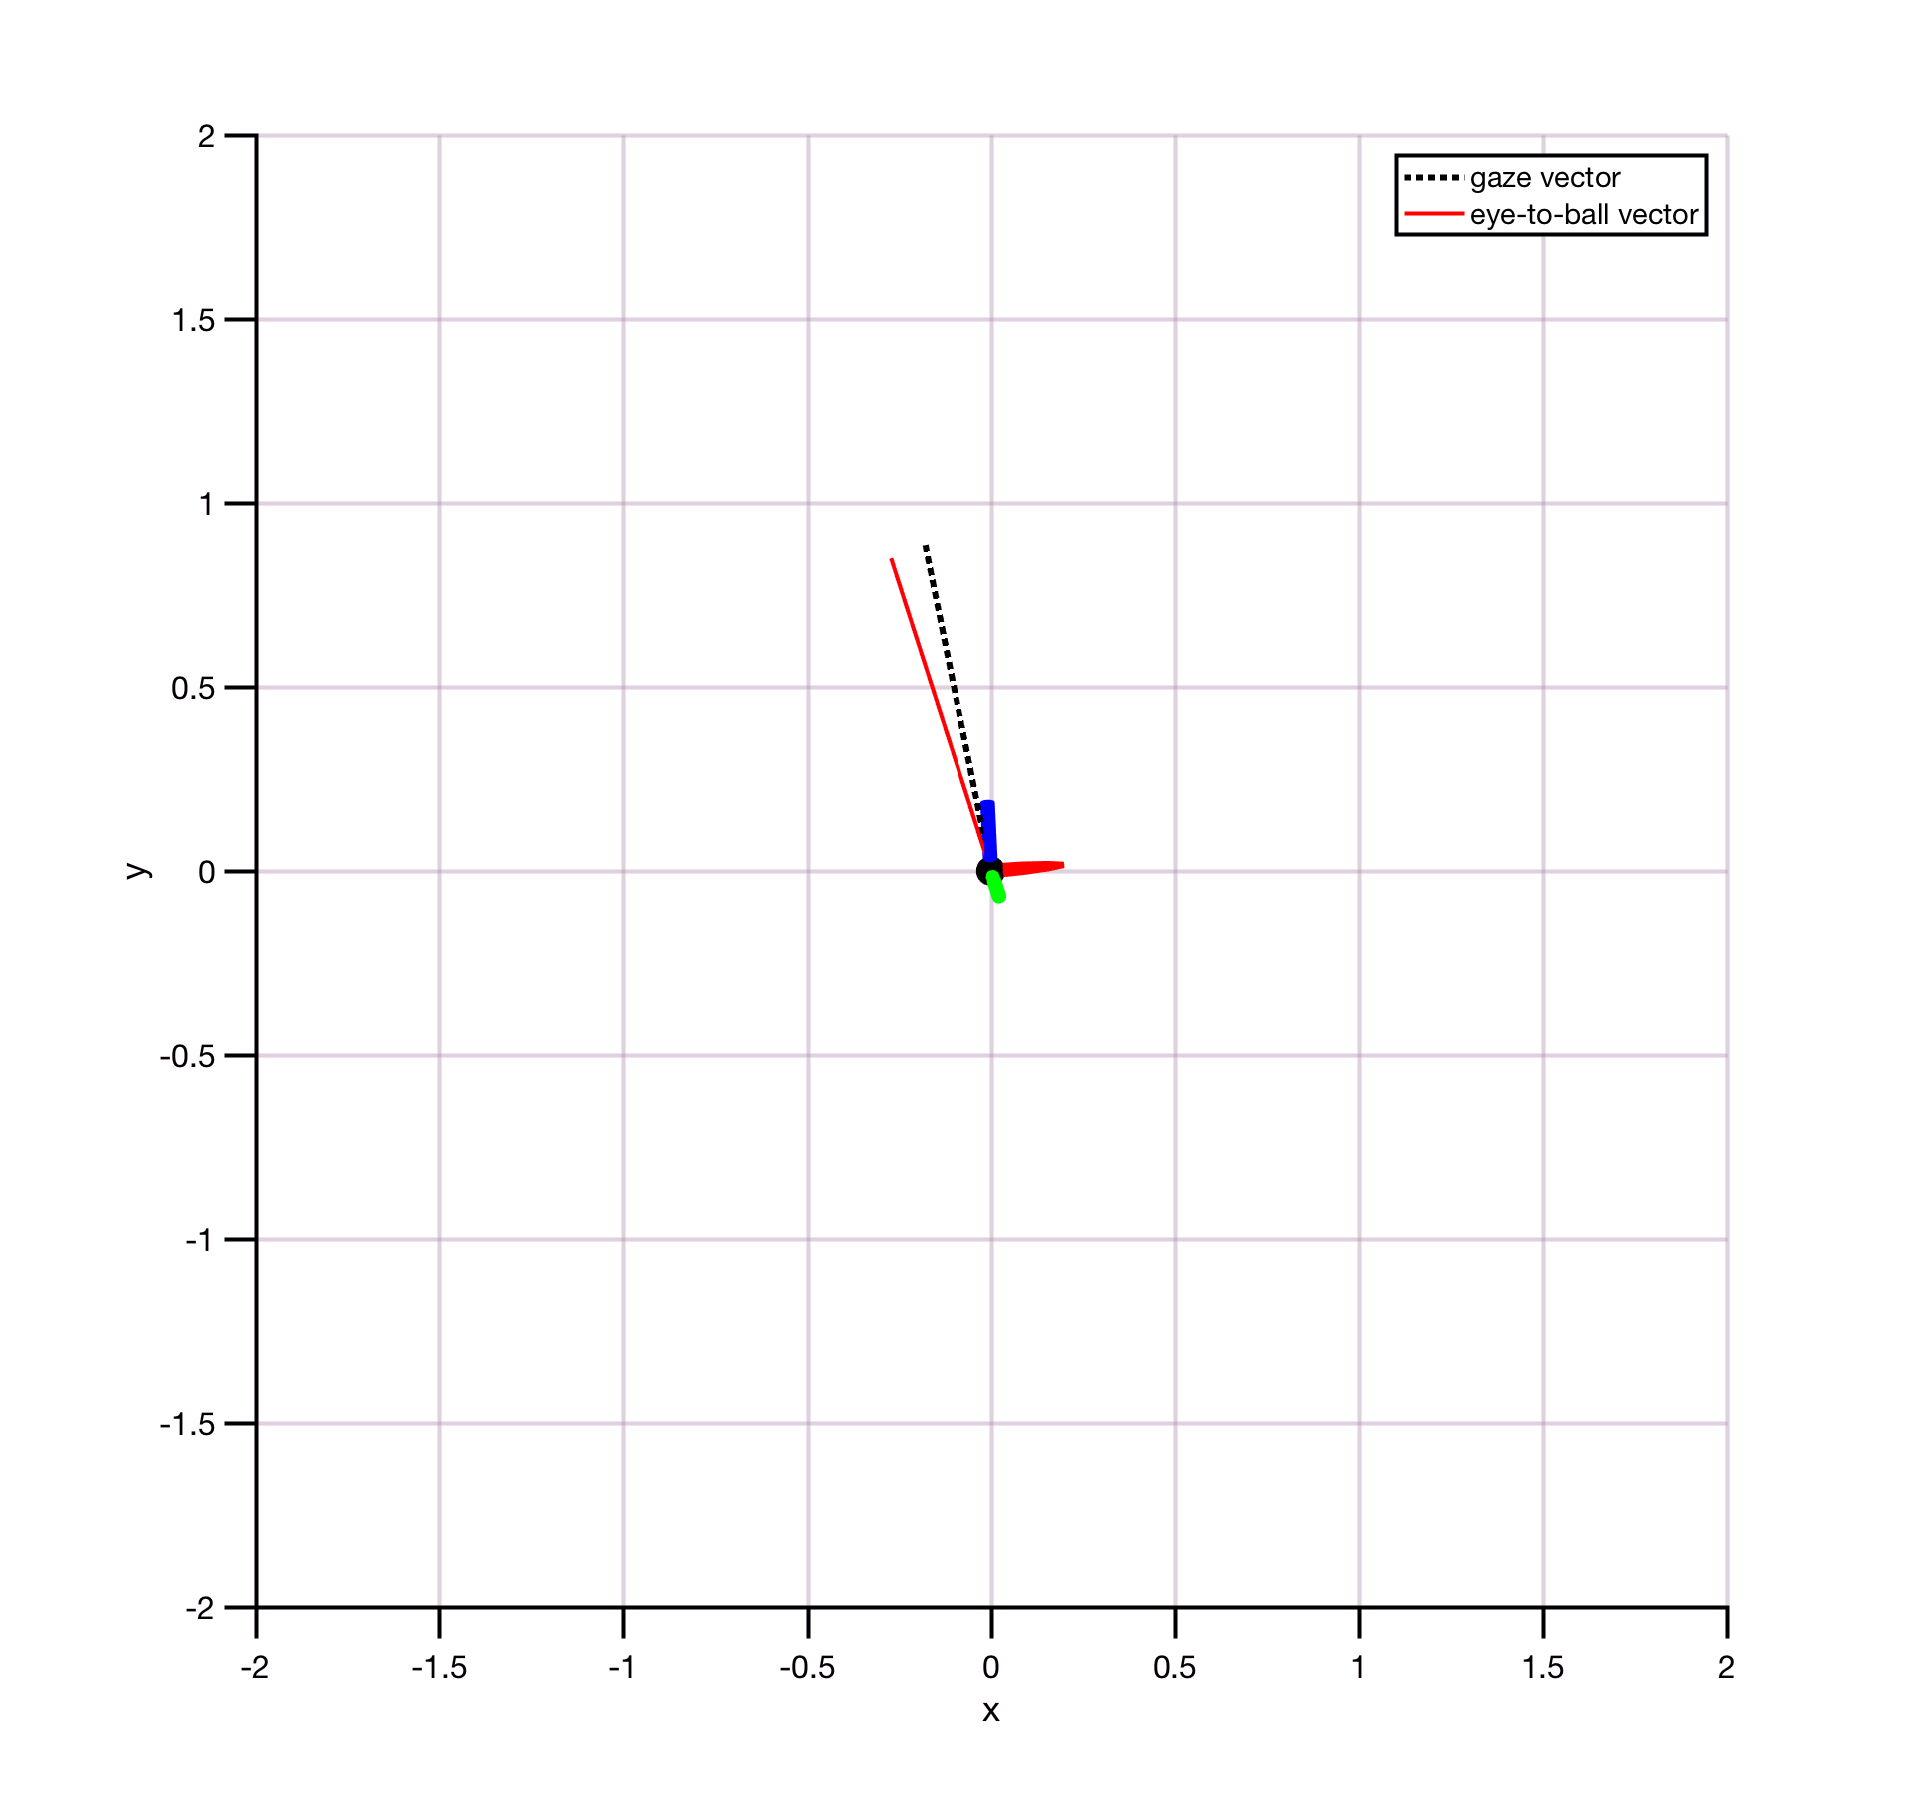


legend([gL,bL],{'gaze vector','eye-to-ball vector'})
set(2,'Units','Normalized','Position',[0.33 0.047 0.57 0.86]);

Now, lets caculate the angular distance between the GIW direciton and eye to ball direction

etData.giwDir_fr_xyz

ans =    -0.3889    0.0251    0.9209
   -0.3901    0.0253    0.9204
   -0.3893    0.0271    0.9207
   -0.3899    0.0266    0.9205
   -0.3905    0.0295    0.9201
   -0.3900    0.0301    0.9203
   -0.3890    0.0298    0.9208
   -0.3892    0.0309    0.9206
   -0.3877    0.0313    0.9213
   -0.3888    0.0324    0.9207


etData.eyeToBallDir_fr_xyz

ans =    -0.4180    0.0262    0.9081
   -0.4176    0.0313    0.9081
   -0.4173    0.0365    0.9081
   -0.4169    0.0416    0.9080
   -0.4165    0.0468    0.9079
   -0.4161    0.0520    0.9078
   -0.4156    0.0572    0.9077
   -0.4152    0.0622    0.9076
   -0.4148    0.0674    0.9074
   -0.4143    0.0725    0.9073


for frIdx = 1:length(etData.cycEyeInHead_fr_XYZ)
    
    angErr_fr(frIdx) = rad2deg(acos( dot(giwDir_fr_xyz(frIdx,:)', eyeToBallDir_fr_xyz(frIdx,:)')));
    
    giwAzimuthDeg_fr(frIdx) = rad2deg(atan(giwDir_fr_xyz(frIdx,1)./giwDir_fr_xyz(frIdx,3)));
    ballAzimuthDeg_fr(frIdx) = rad2deg(atan(eyeToBallDir_fr_xyz(frIdx,1)./eyeToBallDir_fr_xyz(frIdx,3)));
    diffAzimuthDeg_fr(frIdx) = ballAzimuthDeg_fr(frIdx)-giwAzimuthDeg_fr(frIdx);
    
    giwElevationDeg_fr(frIdx) = rad2deg(atan(giwDir_fr_xyz(frIdx,2)./giwDir_fr_xyz(frIdx,3)));
    ballElevationDeg_fr(frIdx) = rad2deg(atan(eyeToBallDir_fr_xyz(frIdx,2)./eyeToBallDir_fr_xyz(frIdx,3)));
    diffElevationDeg_fr(frIdx) = ballElevationDeg_fr(frIdx)-giwElevationDeg_fr(frIdx);
    
end

Lets plot the erorr for a single trial of data!

idx = find(etData.trialNumber_fr == 5);

trNum = 9;

startFrame = min(find(etData.trialNumber_fr == trNum))

startFrame = 2559


% End on the trial frame when ball hits paddle, floor, or when the last trialFrames == trNum.
endFrame = min( [intersect(find(etData.trialNumber_fr == trNum),find(strcmp(etData.eventFlag_fr,'ballOnPaddle')))...
                 intersect(find(etData.trialNumber_fr == trNum),find(strcmp(etData.eventFlag_fr,'ballOnFloor'))) ...
                 min( find(etData.trialNumber_fr == trNum,1,'last') )])

endFrame = 2679

             
fr = startFrame:endFrame;


figure(3)
hold on
cla
time_fr = [0, cumsum(diff(etData.frameTime_fr(fr)))];
s1 = scatter(time_fr,diffAzimuthDeg_fr(fr),20,'Filled','MarkerFaceColor','r')

s1 =   Scatter (azimuth) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: [1 0 0]
           SizeData: 20
          LineWidth: 0.5000
              XData: [1x121 double]
              YData: [1x121 double]
              ZData: [1x0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


s2 = scatter(time_fr,diffElevationDeg_fr(fr),20,'Filled','MarkerFaceColor','c')

s2 =   Scatter (elevation) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: [0 1 1]
           SizeData: 20
          LineWidth: 0.5000
              XData: [1x121 double]
              YData: [1x121 double]
              ZData: [1x0 double]
              CData: [0.8500 0.3250 0.0980]

  Show all properties


s3 = scatter(time_fr,angErr_fr(fr),20,'Filled','MarkerFaceColor','k')

s3 =   Scatter (combined) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: [0 0 0]
           SizeData: 20
          LineWidth: 0.5000
              XData: [1x121 double]
              YData: [1x121 double]
              ZData: [1x0 double]
              CData: [0.9290 0.6940 0.1250]

  Show all properties


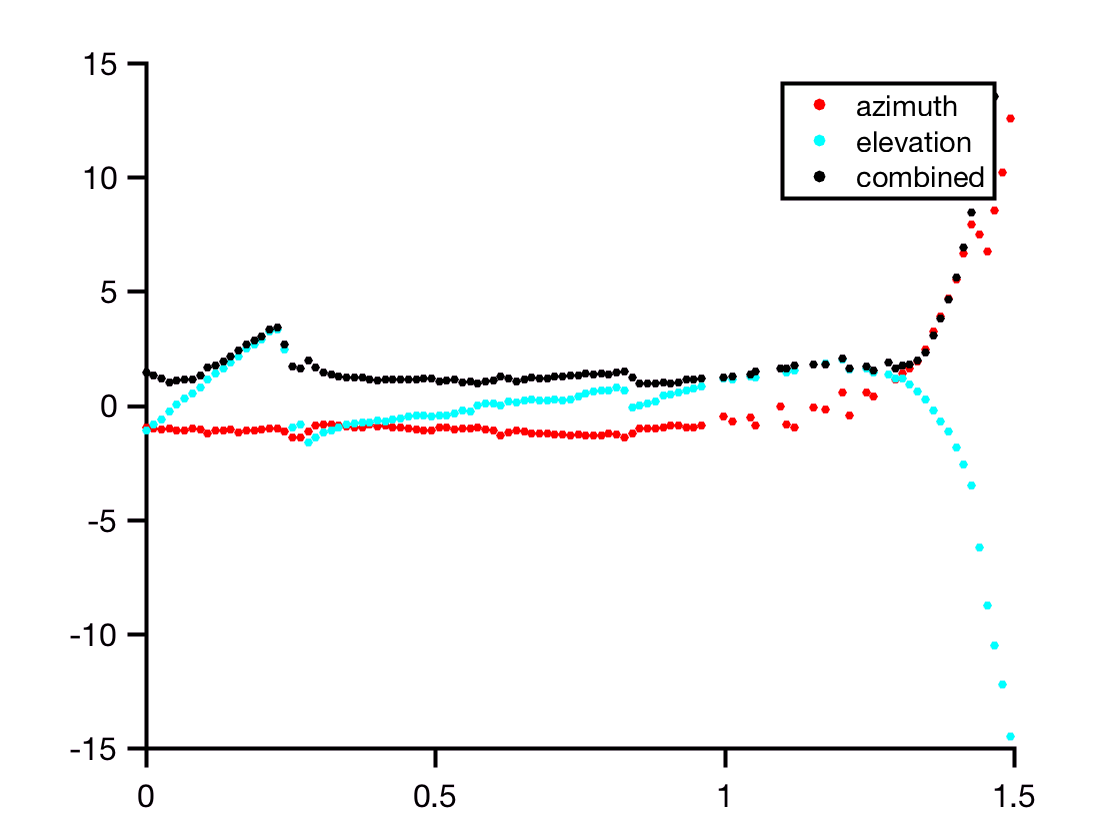

legend([s1, s2,s3],{'azimuth','elevation','combined'})
ylim([-15,15])

Lets compile mean accuracy at the time the ball reappears for mulitple frames

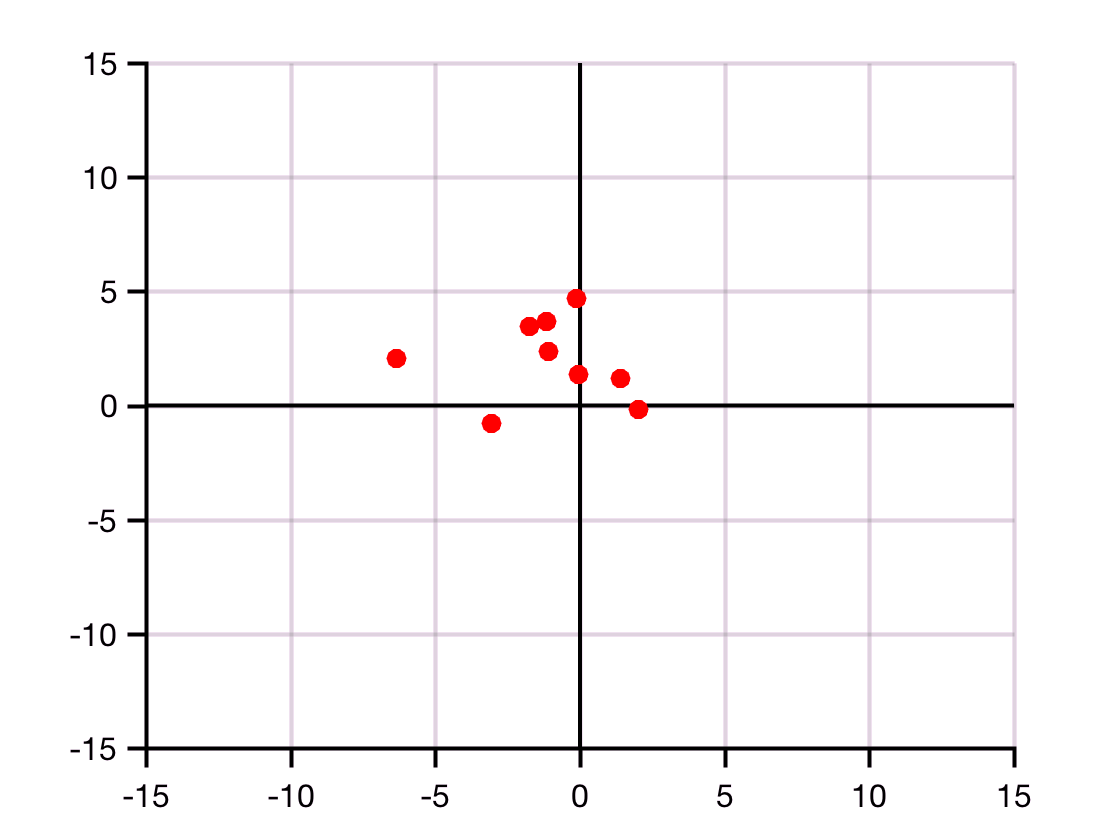

% Get all frames in which the ball reappears (once per trial)
ballRenderOn_tr = find(strcmp(etData.eventFlag_fr,'ballRenderOn'));

azErrorAtBallOn_tr = diffAzimuthDeg_fr(ballRenderOn_tr);
elErrorAtBallOn_tr  = diffElevationDeg_fr(ballRenderOn_tr);

figure(4)
cla
hold on
grid on
axisLimits = 15;
xlim([-axisLimits ,axisLimits ])
ylim([-axisLimits ,axisLimits ])
line([0,0],ylim,'Color','k');
line(xlim,[0,0],'Color','k');

s1 = scatter(azErrorAtBallOn_tr, elErrorAtBallOn_tr,100,'Filled','MarkerFaceColor','r');

So, most error was within 5 degrees of the fovea!